%{ 
Group 3:
1. Steve Vinsensius Jo - V01099466
2. Likkhith Krishnamurthy Aditya - V01098937
%}
clear all;

Task 1

Load the Exercise 4 data set. This data comprises 1000 samples from 2 classes in 100 measurement dimensions.

load("Exercise_4_Data.mat")
whos

  Name               Size               Bytes  Class     Attributes

  Test_indx          1x750               6000  double              
  Train_indx         1x250               2000  double              
  a               1000x100             800000  double              
  classes            1x1000              8000  double              




A = a;
y = double(classes(:));
[NDATA, NDIMS] = size(A);
fprintf('%d samples in %d dimensions: %d in class 0, %d in class 1\n', NDATA, NDIMS, sum(y == 0), sum(y == 1));

1000 samples in 100 dimensions: 562 in class 0, 438 in class 1



dimStd = std(A);
[~, iMax] = max(dimStd);
[~, iMin] = min(dimStd);
fprintf('Standard deviation of the dimensions: largest %.3g (dimension %d), smallest %.3g (dimension %d), median %.3g\n', dimStd(iMax), iMax, dimStd(iMin), iMin, median(dimStd));

Standard deviation of the dimensions: largest 3.91e+08 (dimension 81), smallest 9.93e-09 (dimension 23), median 18


This dataset contains the 1000 x 100 data matrix a, the classification labels (562 data points belong to class 0, 438 data points belong to class 1) as well as a pre-split train/test data set. The variables have wildly varying ranges, with standard deviations ranging between roughly 1e-8 (for variable 23) and 4e8 (for variable 81), with a median of 18 over this range.

Task 2

Comment on whether the available data represents a dense sampling of this high dimensional space and, if you assumed both data classes were Gaussian distributed, then discuss how many data samples would be required to provide a sufficient dense sampling of the data across all of its dimensions

samplesPerAxis = NDATA^(1/NDIMS);
fprintf('%d samples in %d dimensions = %.3f samples per axis\n', NDATA, NDIMS, samplesPerAxis);

1000 samples in 100 dimensions = 1.072 samples per axis


fprintf('Samples needed for 2 per axis: %.2e; for 10 per axis: 1e%d\n', 2^NDIMS, NDIMS);

Samples needed for 2 per axis: 1.27e+30; for 10 per axis: 1e100



Z = (A - mean(A)) ./ std(A);
sq = sum(Z.^2, 2);
D = sqrt(max(sq + sq' - 2*(Z*Z'), 0));
D(1:NDATA+1:end) = NaN;
nnDist = min(D, [], 2);
fprintf('Nearest-neighbor distance: %.1f on average; distance between two samples: %.1f to %.1f (mean %.1f)\n', mean(nnDist), min(D(:)), max(D(:)), mean(D(~isnan(D))));

Nearest-neighbor distance: 11.4 on average; distance between two samples: 9.5 to 18.6 (mean 14.1)



nParams = NDIMS + NDIMS*(NDIMS + 1)/2;
fprintf('A full Gaussian model has %d parameters per class (%d means, %d covariance entries)\n', nParams, NDIMS, NDIMS*(NDIMS + 1)/2);

A full Gaussian model has 5150 parameters per class (100 means, 5050 covariance entries)


As far as the current data volume is concerned, which is 1000 data points, it is not really a dense set in the above 100-dimensional space because of the curse of dimensionality where an exponential increase occurs in the volume of the space when the number of dimensions increases. In other words, only 1.07 points per axis make up 1000 data points. In order to have even a sparse mesh with 2 points per axis, one needs 2^100 = 1.3e30 points. This is confirmed by the distances as well: after normalizing the data, the nearest neighbor of each point is 11.4 units away, whereas the distance between two points is 9.5 to 18.6 units (average 14.1).

Assuming both classes are Gaussian, we only need enough samples to estimate the mean vector and the covariance matrix of each class: 100 + (100 x 101)/2 = 5,150 parameters per class, more than 10,000 across the two classes. The covariance matrix is singular with fewer than 101 samples per class, and with the common rule of about 10 samples per parameter we would need roughly 50,000 samples per class, about 100,000 in total, while only 1000 are available (250 for training). This gap between what is available and what is needed motivates dimensionality reduction techniques such as PCA and FLD, which reduce the number of parameters that must be estimated.

Task 3

Randomly partition the data into training and test sets where the training set represents 25% of the data and the test set represents the remaining 75% of the data.

trainIdx = double(Train_indx(:));
testIdx  = double(Test_indx(:));

TRAIN_IND = trainIdx(1:200)';
VAL_IND   = trainIdx(201:250)';
TEST_IND  = testIdx';

fprintf('Training set: %d samples (%.0f%%), test set: %d samples (%.0f%%)\n', numel(trainIdx), 100*numel(trainIdx)/NDATA, numel(testIdx), 100*numel(testIdx)/NDATA);

Training set: 250 samples (25%), test set: 750 samples (75%)


fprintf('Samples in both sets: %d; samples covered: %d of %d\n', numel(intersect(trainIdx, testIdx)), numel(union(trainIdx, testIdx)), NDATA);

Samples in both sets: 0; samples covered: 1000 of 1000


fprintf('Class 0 / class 1 counts: training %d / %d, test %d / %d\n', sum(y(trainIdx) == 0), sum(y(trainIdx) == 1), sum(y(testIdx) == 0), sum(y(testIdx) == 1));

Class 0 / class 1 counts: training 116 / 134, test 446 / 304



Xtr = A(trainIdx, :);   ytr = y(trainIdx);
Xte = A(testIdx, :);    yte = y(testIdx);

The data file already contains the 25/75 split (Train_indx and Test_indx), and we will use them such that each algorithm is evaluated using the same samples for training and testing. All of PCA, FLD, and Bayes are trained on all 250 training samples and tested on the remaining 750 test samples. Neural network (Task 11) has the same training and testing sets; its validation set contains the last 50 out of the 250 training samples, meaning that the validation set is a subset of the training set, while the other 200 are used to train (set the weights).

Task 4

Use the training data to construct a Principal Component Analysis (PCA) approach to reduce the data to 3 dimensions and apply this dimensionality reduction to the test data

muTr = mean(Xtr);
[V, L] = eig(cov(Xtr));
[lambda, order] = sort(diag(L), 'descend');
V = V(:, order);
W_pca = V(:, 1:3);

Ztr_pca = (Xtr - muTr) * W_pca;
Zte_pca = (Xte - muTr) * W_pca;

fprintf('Five largest eigenvalues: %s\n', mat2str(lambda(1:5)', 4));

Five largest eigenvalues: [1.45e+17 4590 3452 3162 2696]


fprintf('Share of the total variance kept by 3 components: %.10f\n', sum(lambda(1:3))/sum(lambda));

Share of the total variance kept by 3 components: 1.0000000000


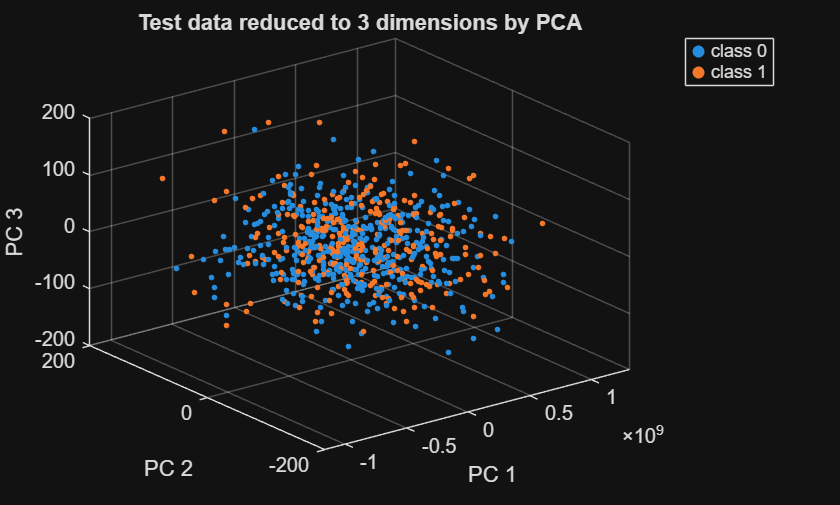


figure
scatter3(Zte_pca(yte == 0,1), Zte_pca(yte == 0,2), Zte_pca(yte == 0,3), 8, 'filled')
hold on
scatter3(Zte_pca(yte == 1,1), Zte_pca(yte == 1,2), Zte_pca(yte == 1,3), 8, 'filled')
hold off
xlabel('PC 1'), ylabel('PC 2'), zlabel('PC 3')
legend('class 0', 'class 1'), title('Test data reduced to 3 dimensions by PCA'), grid on, view(3)

PCA takes the eigenvectors of the training covariance matrix and keeps the 3 with the largest eigenvalues; the test data is centered with the training mean and projected onto the same 3 eigenvectors. The first eigenvalue (1.45e17) is about 3e13 times the second, because dimension 81 alone has a standard deviation of about 4e8. The 3 components therefore keep essentially 100% of the variance, but almost all of it is the variance of dimension 81. The plot shows the two classes completely overlapping in the reduced space.

Task 5

Train a Bayes classifier on the PCA reduced data and comment on the classifier’s performance and discuss why the performance either improved or did not improve.

model_pca = bayesTrain(Ztr_pca, ytr);
yhat_pca = bayesPredict(model_pca, Zte_pca);
fprintf('PCA + Bayes: training accuracy %.2f%%, test accuracy %.2f%%\n', 100*mean(bayesPredict(model_pca, Ztr_pca) == ytr), 100*mean(yhat_pca == yte));

PCA + Bayes: training accuracy 56.00%, test accuracy 46.13%


fprintf('Priors learned from the training set: class 0 %.3f, class 1 %.3f\n', model_pca.prior);

Priors learned from the training set: class 0 0.464, class 1 0.536


fprintf('Test samples predicted as class 1: %.1f%% (actual share %.1f%%)\n', 100*mean(yhat_pca == 1), 100*mean(yte == 1));

Test samples predicted as class 1: 77.3% (actual share 40.5%)


fprintf('Always predicting the larger test class would score %.2f%%\n', 100*max(mean(yte == 0), mean(yte == 1)));

Always predicting the larger test class would score 59.47%


printConfusion(yte, yhat_pca)

                 predicted 0   predicted 1
   true class 0          106           340
   true class 1           64           240


The accuracy of the PCA-based Bayes classifier is only 46.1%, which is lower than pure random chance (50%) and well below the 59.5% we would get by always predicting class 0, the larger test class. The poor performance comes from the fact that PCA is an unsupervised approach: it keeps the top 3 principal components, which account for the maximum variance in the data, but these directions are not the ones that discriminate between the two classes. Here they are dimension 81 and mixtures of other high-variance dimensions, so the discriminative information was discarded by the reduction (Task 9 shows where it is).

The accuracy falls below 50% because of the priors. Class 1 is 54% of the training set (prior 0.536), so with almost identical class models the classifier predicts class 1 for 77% of the test samples, while only 41% of them really are class 1.

Task 6

Discuss whether PCA is a correct approach to apply for addressing classification problems and present clear arguments as to why (or why not).

sTr = std(Xtr);
Str = (Xtr - muTr) ./ sTr;
Ste = (Xte - muTr) ./ sTr;
[Vs, Ls] = eig(cov(Str));
[~, os] = sort(diag(Ls), 'descend');
Ws = Vs(:, os(1:3));
model_spca = bayesTrain(Str * Ws, ytr);
fprintf('PCA on standardized data + Bayes: test accuracy %.2f%%\n', 100*mean(bayesPredict(model_spca, Ste * Ws) == yte));

PCA on standardized data + Bayes: test accuracy 66.27%


Principal Component Analysis is an unsupervised approach which determines the directions of maximum variance without using the class labels information. In a classification problem, PCA is not the right choice since the directions of maximum variance might not correspond to the best separation of the classes. The discriminative information might be lost in the process of reduction and the classifier would end up having no informative features at all. This is precisely what has occurred in this case (46.1% in Task 5): the class information is contained in the 23rd dimension, which has the smallest variance and thus is discarded by PCA.

PCA is also a scale-dependent approach: dimension 81 has high variance due to its units. Standardizing all the dimensions prior to PCA (the code above) results in much higher accuracy (66.3%), yet still quite low due to the fact that PCA uses variance rather than the class separability to rank the dimensions. PCA is good at compression, noise removal and visualization, and can be used before classification if there is significant separability between the classes compared to the variance within them, yet otherwise it is better to use FLD.

Task 7

Use the training data to construct a Fisher Linear Discriminant and use the learned discriminant to reduce the test data to one dimension.

[w_fld, Sw, dm] = fisherDirection(Str, ytr);
ztr_fld = Str * w_fld;
zte_fld = Ste * w_fld;

[Ve, De] = eig(Sw \ (dm * dm'));
[~, k] = max(real(diag(De)));
v = real(Ve(:, k)) / norm(real(Ve(:, k)));
fprintf('|cosine| between w and the top eigenvector of inv(Sw)*Sb: %.6f\n', abs(v' * w_fld));

|cosine| between w and the top eigenvector of inv(Sw)*Sb: 1.000000



D0 = Xtr(ytr == 0, :) - mean(Xtr(ytr == 0, :));
D1 = Xtr(ytr == 1, :) - mean(Xtr(ytr == 1, :));
fprintf('Condition number of Sw: %.2e for the standardized data, %.2e for the raw data\n', cond(Sw), cond(D0'*D0 + D1'*D1));

Condition number of Sw: 4.26e+04 for the standardized data, 9.63e+29 for the raw data


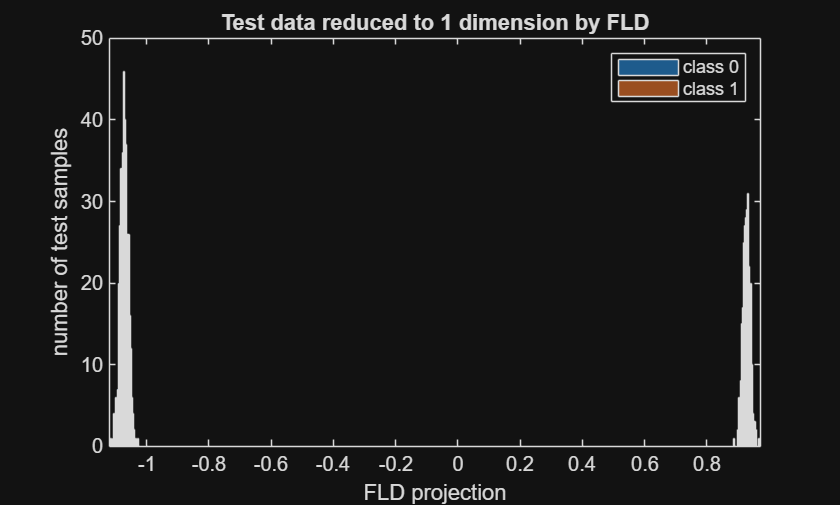


figure
histogram(zte_fld(yte == 0), 30)
hold on
histogram(zte_fld(yte == 1), 30)
hold off
xlabel('FLD projection'), ylabel('number of test samples')
legend('class 0', 'class 1'), title('Test data reduced to 1 dimension by FLD')

FLD seeks the vector w that maximizes J(w)=(w'*Sb*w)/(w'*Sw*w), which is the ratio of the variance of projected class means to the variance within each class. For two classes, the optimal w is simply w=inv(Sw)*(m1-m0), which is the first eigenvector of inv(Sw)*Sb. We perform it on normalized data in the training set. Normalization of features does not affect the FLD transformation, but the condition number of the raw within-class scatter matrix is roughly 3e30 and solving the problem using the matrix directly is unstable (MATLAB gives warning about singular matrix), while the normalized matrix has a condition number of roughly 4e4. The test data is normalized with the same training mean and standard deviation and then projected on w; see the resulting histogram.

Task 8

Train a Bayes classifier on the FLD reduced data and comment on the classifier’s performance and discuss why the performance either improved or did not improve.

model_fld = bayesTrain(ztr_fld, ytr);
yhat_fld = bayesPredict(model_fld, zte_fld);
fprintf('FLD + Bayes: training accuracy %.2f%%, test accuracy %.2f%%\n', 100*mean(bayesPredict(model_fld, ztr_fld) == ytr), 100*mean(yhat_fld == yte));

FLD + Bayes: training accuracy 100.00%, test accuracy 100.00%


fprintf('Projected class means: %.3f and %.3f; within-class standard deviations: %.4f and %.4f\n', model_fld.mu{1}, model_fld.mu{2}, sqrt(model_fld.Sigma{1}), sqrt(model_fld.Sigma{2}));

Projected class means: -1.072 and 0.928; within-class standard deviations: 0.0077 and 0.0080


printConfusion(yte, yhat_fld)

                 predicted 0   predicted 1
   true class 0          446             0
   true class 1            0           304


The accuracy of the Bayes classifier with FLD is 100% for both the training and the testing data. This is a big difference from the PCA classifier (46.1%) since FLD is a supervised method which maximizes the scatter ratio between the classes to that of within the classes, and therefore the single dimension retained has the maximum discriminating power. In the projection, the class means are approximately -1.07 and 0.93, and the spread within each class is approximately 0.008, giving the classes a separation of 250 standard deviations.

Task 9

Discuss why the PCA and FLD approaches resulted in different dimensionality reductions of the data. Use the eigenvectors produced from both approaches to determine which feature vectors each approach focused on in its dimensionality reduction process.

Based on the No Free Lunch Theorem, discuss whether or not it is always the case that FLD will outperform PCA ? .

for k = 1:3
    [~, o] = sort(abs(W_pca(:, k)), 'descend');
    fprintf('PCA eigenvector %d: largest loadings on dimensions %s, values %s\n', k, mat2str(o(1:3)'), mat2str(W_pca(o(1:3), k)', 3));
end

PCA eigenvector 1: largest loadings on dimensions [81 85 89], values [-1 1.2e-08 1.09e-08]
PCA eigenvector 2: largest loadings on dimensions [85 42 89], values [0.884 0.334 0.109]
PCA eigenvector 3: largest loadings on dimensions [42 85 6], values [-0.872 0.35 -0.148]


[~, o] = sort(abs(w_fld), 'descend');
fprintf('FLD eigenvector: largest weights on dimensions %s, values %s\n', mat2str(o(1:5)'), mat2str(w_fld(o(1:5))', 3));

FLD eigenvector: largest weights on dimensions [23 45 66 51 92], values [1 -0.00191 -0.00183 0.00182 0.00167]


fprintf('Largest |loading| of dimension %d on the 3 PCA eigenvectors: %.1e\n', o(1), max(abs(W_pca(o(1), :))));

Largest |loading| of dimension 23 on the 3 PCA eigenvectors: 1.8e-11



ex = load('Exercise_4_Data_extra.mat');
Xe = ex.data;
ye = double(ex.class(:));
Xe_tr = Xe(trainIdx, :);   ye_tr = ye(trainIdx);
Xe_te = Xe(testIdx, :);    ye_te = ye(testIdx);

mue = mean(Xe_tr);
[Vx, Lx] = eig(cov(Xe_tr));
[~, kx] = max(diag(Lx));
pe = Vx(:, kx);
acc_e_pca = mean(bayesPredict(bayesTrain((Xe_tr - mue)*pe, ye_tr), (Xe_te - mue)*pe) == ye_te);
we = fisherDirection(Xe_tr, ye_tr);
acc_e_fld = mean(bayesPredict(bayesTrain(Xe_tr*we, ye_tr), Xe_te*we) == ye_te);
acc_e_nn = mean(nn1Classify(Xe_tr, ye_tr, Xe_te) == ye_te);
fprintf('Extra data: PCA + Bayes %.1f%%, FLD + Bayes %.1f%%, 1-nearest neighbor %.1f%%\n', 100*acc_e_pca, 100*acc_e_fld, 100*acc_e_nn);

Extra data: PCA + Bayes 48.0%, FLD + Bayes 47.5%, 1-nearest neighbor 91.6%


fprintf('Extra data class means: [%.2f %.2f] and [%.2f %.2f]\n', mean(Xe(ye == 0, :)), mean(Xe(ye == 1, :)));

Extra data class means: [-0.01 0.06] and [-0.02 -0.00]


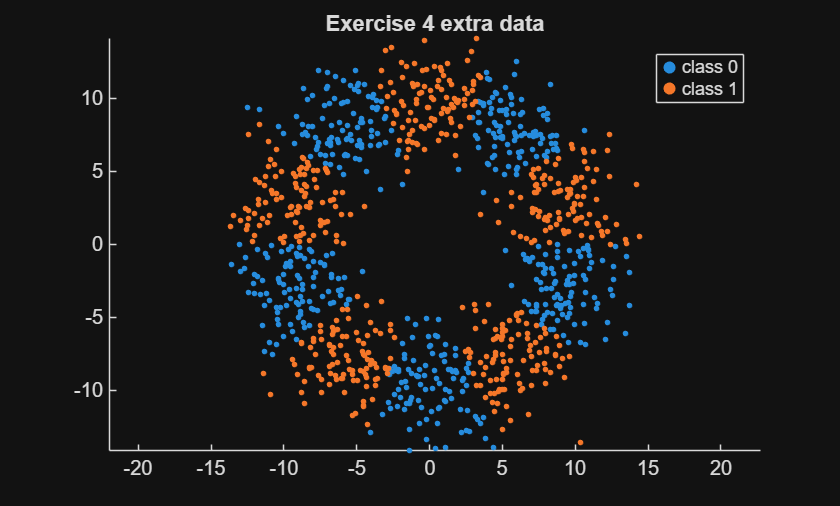


figure
scatter(Xe(ye == 0, 1), Xe(ye == 0, 2), 8, 'filled')
hold on
scatter(Xe(ye == 1, 1), Xe(ye == 1, 2), 8, 'filled')
hold off
axis equal, legend('class 0', 'class 1'), title('Exercise 4 extra data')


rng(11);
n = 500;
Xs = [randn(n, 2); randn(n, 2) .* [5 1] + [0 0.5]];
ys = [zeros(n, 1); ones(n, 1)];
ps = randperm(2*n);
s_tr = ps(1:250);   s_te = ps(251:end);
[Vy, Ly] = eig(cov(Xs(s_tr, :)));
[~, ky] = max(diag(Ly));
vy = Vy(:, ky);
acc_y_pca = mean(bayesPredict(bayesTrain(Xs(s_tr, :)*vy, ys(s_tr)), Xs(s_te, :)*vy) == ys(s_te));
wy = fisherDirection(Xs(s_tr, :), ys(s_tr));
acc_y_fld = mean(bayesPredict(bayesTrain(Xs(s_tr, :)*wy, ys(s_tr)), Xs(s_te, :)*wy) == ys(s_te));
fprintf('Spread example: PCA + Bayes %.1f%%, FLD + Bayes %.1f%%\n', 100*acc_y_pca, 100*acc_y_fld);

Spread example: PCA + Bayes 82.7%, FLD + Bayes 60.1%


PCA and FLD give different dimensionality reductions because they aim at different goals. PCA finds the directions with maximum variance in the data, irrespective of the class labels, while FLD finds the direction with maximum class separation relative to the within-class variance. The eigenvectors show the difference. PCA's first eigenvector is dimension 81 alone (a weight of size 1), and the second and third are mostly dimensions 85 and 42, the next highest-variance dimensions; dimension 23's weights on all three are essentially zero (of the order of 1e-11). The FLD weight vector puts almost all of its weight on one feature, dimension 23 (size 1, every other weight below 0.002), meaning that the classification information is carried by that one feature only, the dimension with the smallest variance.

From the No Free Lunch theorem, FLD does not have to be better than PCA: no algorithm performs better than all others on all possible problems. FLD wins here because the classes differ in their means along one direction, which is exactly what FLD looks for. The extra data set is the opposite case. Its two classes occupy alternating 36 degree sectors of a ring, so both have a mean of about (0, 0) and the same covariance; FLD has nothing to separate and scores 47.5%, the same as PCA (48.0%), while a 1-nearest-neighbor classifier reaches 91.6%. When the classes differ mainly in spread, PCA can even beat FLD: in the second example class 1 is five times more spread out along one axis, and PCA scores about 80% against about 60% for FLD.

Task 10

Discuss whether the performance would have improved if a higher percentage of the data was used in training of the PCA-based classification system.

FRACTIONS = [0.25 0.50 0.75 0.90];
N_REPEATS = 20;
rng(10);
for f = FRACTIONS
    accs = zeros(N_REPEATS, 1);
    for r = 1:N_REPEATS
        perm = randperm(NDATA);
        nTr = round(f*NDATA);
        itr = perm(1:nTr);
        ite = perm(nTr+1:end);
        mu_r = mean(A(itr, :));
        [Vr, Lr] = eig(cov(A(itr, :)));
        [~, orr] = sort(diag(Lr), 'descend');
        Wr = Vr(:, orr(1:3));
        mdl = bayesTrain((A(itr, :) - mu_r)*Wr, y(itr));
        accs(r) = mean(bayesPredict(mdl, (A(ite, :) - mu_r)*Wr) == y(ite));
    end
    fprintf('Training on %2.0f%% of the data: PCA + Bayes test accuracy %.1f%% on average (%.1f%% to %.1f%%)\n', 100*f, 100*mean(accs), 100*min(accs), 100*max(accs));
end

Training on 25% of the data: PCA + Bayes test accuracy 53.3% on average (47.3% to 56.1%)
Training on 50% of the data: PCA + Bayes test accuracy 54.5% on average (52.0% to 57.8%)
Training on 75% of the data: PCA + Bayes test accuracy 54.1% on average (50.8% to 59.6%)
Training on 90% of the data: PCA + Bayes test accuracy 53.1% on average (46.0% to 62.0%)


fprintf('Share of the larger class in the whole data set: %.1f%%\n', 100*mean(y == 0));

Share of the larger class in the whole data set: 56.2%


No. More data for training provides an increasingly precise estimation of the covariance matrix, which leads to improved estimations of the principal components and the class models. However, the problem remains unchanged – PCA does not consider the class labels, so that even the most precise estimation of the covariance matrix cannot produce the principal components pointing in the direction of discrimination. They never will, as long as the dimension 23 has the minimum variance regardless of the amount of training samples used. Indeed, the experiment shows that even after 20 randomly generated splits for each training fraction from 25% to 90%, the mean test accuracy remains at around 53% to 55%. This result is slightly higher than the one for always choosing the majority class (56.2%), but still significantly worse than the accuracy obtained for the provided split (46.1%). The slight superiority of random splits is caused by similar class proportions in the training and test sets.

Task 11

Use Matlab’s neural network toolbox (via the nnstart command) to train a shallow neural network on the original unreduced data set, using the exact same training and test set as for your PCA and FLD classifiers, i.e., use exactly the same data point within the training and test sets. Draw your validation set from the training set, It should be noted that given validation sets are used to change neural network parameters they formally form part of the “training” of the neural network. Test data is data the neural network has never seen before.

You will need to manually set the training, testing, and validation indices when setting up your neural network code. Check the help page for the Matlab’s divideind function to learn how to ensure the exact composition of your training, test, and validation data sets.

It is critical when comparing classifier performance to ensure they have seen and been evaluated on exactly the same training, test, and validation data sets, as otherwise random variations in random draws of these data sets can lead to significant variations in the results.

Discuss in detail why the PCA, FLD, and neural network approaches arrive at different solution to the problem. i.e., different decision boundaries, even when they have been trained and tested using exactly persample identical training, validation, and testing data sets.

X = A';
T = double([y' == 0; y' == 1]);

SEEDS = 1:5;
acc_nn = zeros(size(SEEDS));
for k = 1:numel(SEEDS)
    net = trainShallowNet(X, T, TRAIN_IND, VAL_IND, TEST_IND, SEEDS(k), true);
    acc_nn(k) = mean(vec2ind(net(X(:, TEST_IND))) - 1 == yte');
    if k == 1
        net11 = net;
    end
end
fprintf('Neural network, default input processing: test accuracy %s%% for seeds %s\n', mat2str(round(100*acc_nn, 2)), mat2str(SEEDS));

Neural network, default input processing: test accuracy [100 100 100 100 100]% for seeds [1 2 3 4 5]


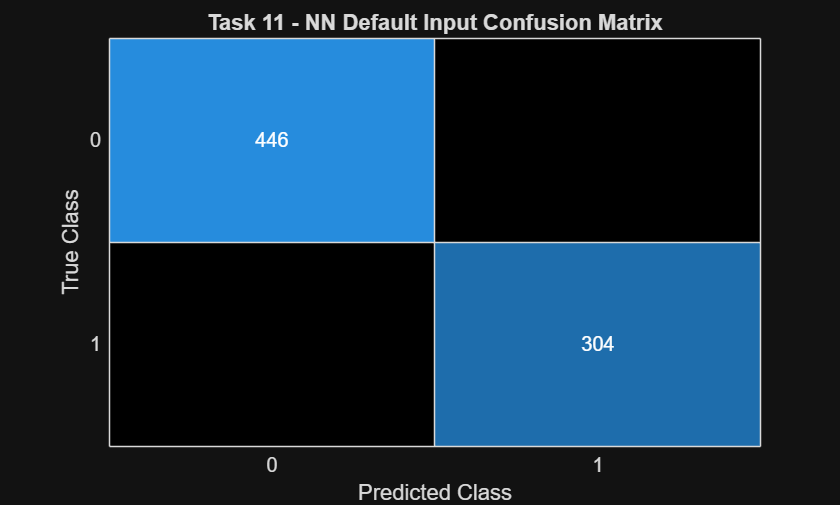


% plotconfusion(T(:, TEST_IND), net11(X(:, TEST_IND)))
pred = vec2ind(net11(X(:, TEST_IND))) - 1;
figure;
confusionchart(yte', pred);
title('Task 11 - NN Default Input Confusion Matrix');

The network is the one the nnstart Pattern Recognition app creates (patternnet with 10 tansig hidden neurons and 2 softmax outputs, trained with scaled conjugate gradient). divideind fixes the split: 200 of the 250 training samples fit the weights, the other 50 are the validation set (used for early stopping, so they are part of training), and the test set is the same 750 samples used for PCA and FLD. Normalization makes the default network work at 100% (practically speaking) on the test set for each seed, along with FLD.

All three techniques find different boundaries in the same dataset since they utilize different optimization procedures and assumptions. PCA finds directions of maximal variance without taking into account the class labels and thus produces an ineffective projection for classification task (the method retains the 81st dimension and discards the 23rd), its boundary has nothing to do with the classes. FLD uses the closed-form solution for finding one linear direction of maximal class separability. Its boundary is practically the same hyperplane, or threshold in the 23rd dimension. Neural network learns the nonlinear boundary iteratively through the backpropagation of weights. No assumptions are made about the data distribution. Its solution also depends on the initialization of weights randomly, early stopping on 50 training samples and the scaling of inputs. That is why all the three boundaries are different although they all classify the test data. There are no data points in most of the 100-dimensional space, and thus nothing constrains the boundaries, and FLD and network can perfectly agree on test points while having very different boundaries.

The default network uses input normalization (mapminmax), which rescales every input to the range [-1, 1]. This brings all 100 features onto the same scale, and in particular turns dimension 23's tiny 2e-8 class difference into about -1 for class 0 and +1 for class 1, a perfectly separating input the network can use right away.

Task 12

Retrain the neural network setting the neural network ”processFcns” parameter as follows:


$$\begin{array}{l}
n=\textrm{patternet};\\
n\ldotp \textrm{inputs}\left\lbrace 1\right\rbrace \ldotp \textrm{processFcns}=\left\lbrace \right\rbrace ;
\end{array}$$


Discuss the changes seen in the neural network’s classification performance and why these changes arise.

acc_raw = zeros(size(SEEDS));
for k = 1:numel(SEEDS)
    net = trainShallowNet(X, T, TRAIN_IND, VAL_IND, TEST_IND, SEEDS(k), false);
    acc_raw(k) = mean(vec2ind(net(X(:, TEST_IND))) - 1 == yte');
    if k == 1
        net12 = net;
    end
end
fprintf('Neural network, no input processing: test accuracy %s%% for seeds %s\n', mat2str(round(100*acc_raw, 2)), mat2str(SEEDS));

Neural network, no input processing: test accuracy [54.4 51.2 65.6 64.27 53.33]% for seeds [1 2 3 4 5]


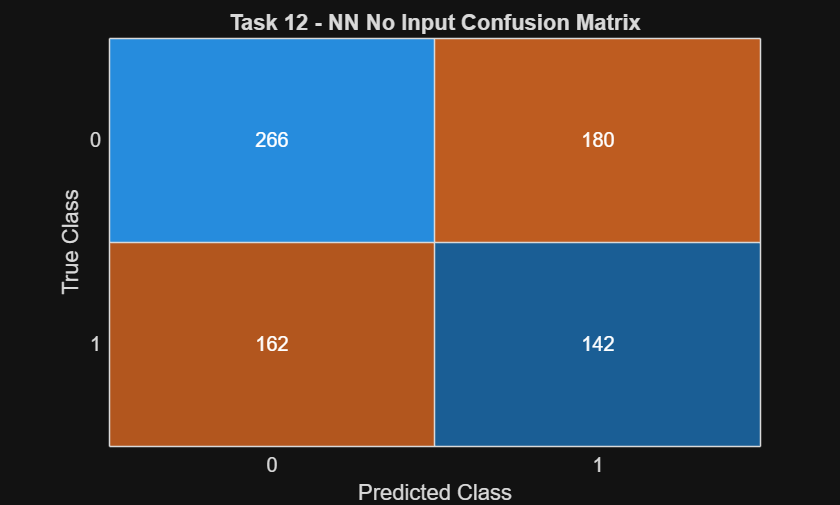


% plotconfusion(T(:, TEST_IND), net12(X(:, TEST_IND)))
pred = vec2ind(net12(X(:, TEST_IND))) - 1;
figure;
confusionchart(yte', pred);
title('Task 12 - NN No Input Confusion Matrix');

When the input normalization is removed (processFcns = {}), the network's accuracy drops well below 100% and changes a lot from seed to seed (printed above). Without normalization the raw values of the features vary enormously across the 100 dimensions: dimension 81 varies by hundreds of millions, while dimension 23's class difference is only 2e-8 on top of a nearly constant 46.8. The gradient updates during training are therefore biased towards the features with the largest magnitudes, and changing dimension 23's weight shifts every sample by almost the same amount, which makes it very hard for the network to detect that this single dimension is the discriminative one. Some seeds can still beat chance, partly because the default initialization (initnw) scales each input's starting weights to that input's range, so dimension 23 starts with a small influence on the hidden neurons; training just cannot strengthen it. This clearly shows that input normalization is not an optional step: like PCA, and unlike FLD, a neural network is sensitive to the scale of its inputs.

Task 13

Look at the dimensionally reduction transform produced via FLD to identify the exact specific feature dimension that contains the classification information. Formally compare this feature dimension to the 99 other feature dimensions within the data set and discuss their observed differences (or similarities).

Now remove the identified feature vector from the data set, and for each of the 1000 rows of the remaining data randomly place the value of the identified feature vector for that row into one of the 99 remaining columns, i.e., randomly scatter the identified feature vector through the data on a row-by-row basis.

Reapply the PCA, FLD, and neural network approaches to this new data and discuss the resulting classification performance of each of the methods and why they occur.

Has the above random transform on the data preserved the property that the data remains perfectly separable? If so, then discuss what pattern classification technique could be used (or trained) such that it retained the ability to perfectly separate the data?

Discuss how a nearest-neighbor classifier perform on this new data sets (and why)?

[~, featIdx] = max(abs(w_fld));
fprintf('The FLD direction is concentrated on dimension %d (weight %.4f)\n', featIdx, w_fld(featIdx));

The FLD direction is concentrated on dimension 23 (weight 1.0000)



n0 = sum(y == 0);   n1 = sum(y == 1);
m0 = mean(A(y == 0, :));   m1 = mean(A(y == 1, :));
v0 = var(A(y == 0, :));    v1 = var(A(y == 1, :));
fisherRatio = (m1 - m0).^2 ./ (v0 + v1);
tStat = (m1 - m0) ./ sqrt(v0/n0 + v1/n1);
others = setdiff(1:NDIMS, featIdx);
fprintf('Dimension %d: mean %.2f, std %.2e, class means %.11f and %.11f, within-class std %.1e and %.1e\n', featIdx, mean(A(:, featIdx)), dimStd(featIdx), m0(featIdx), m1(featIdx), sqrt(v0(featIdx)), sqrt(v1(featIdx)));

Dimension 23: mean 46.81, std 9.93e-09, class means 46.80954306709 and 46.80954308709, within-class std 1.0e-10 and 1.0e-10


fprintf('   Fisher ratio %.3g, t statistic %.0f\n', fisherRatio(featIdx), tStat(featIdx));

   Fisher ratio 2e+04, t statistic 3138


fprintf('Other 99 dimensions: std %.2g to %.2g (median %.2g; largest without dimension %d: %.2g)\n', min(dimStd(others)), max(dimStd(others)), median(dimStd(others)), iMax, max(dimStd(setdiff(others, iMax))));

Other 99 dimensions: std 0.38 to 3.9e+08 (median 19; largest without dimension 81: 62)


fprintf('   Fisher ratio at most %.2g, largest |t| %.1f, |t| above 1.96 in %d of 99\n', ...
    max(fisherRatio(others)), max(abs(tStat(others))), sum(abs(tStat(others)) > 1.96));

   Fisher ratio at most 0.03, largest |t| 3.8, |t| above 1.96 in 32 of 99


fprintf('   class 1 mean below the class 0 mean in %d of 99, by %.2f standard deviations on average\n', sum(m1(others) < m0(others)), mean((m0(others) - m1(others)) ./ dimStd(others)));

   class 1 mean below the class 0 mean in 94 of 99, by 0.10 standard deviations on average


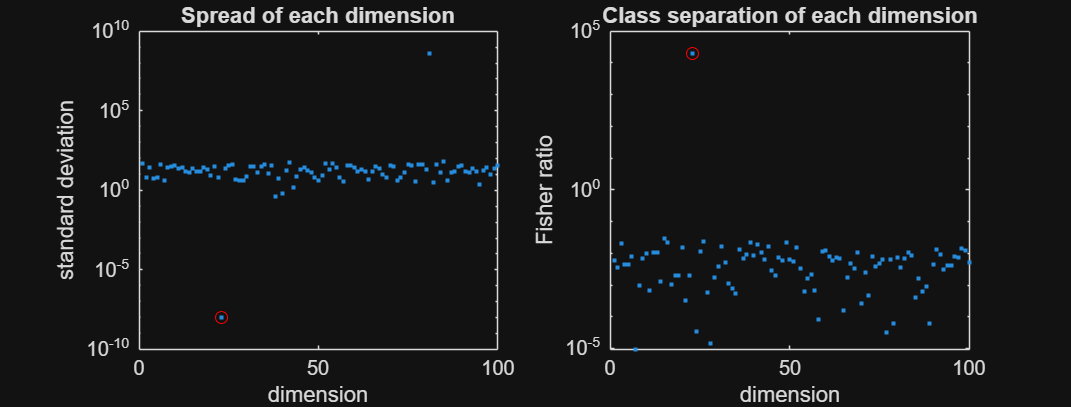


figure('Position', [100 100 1000 380])
subplot(1, 2, 1)
semilogy(1:NDIMS, dimStd, '.', featIdx, dimStd(featIdx), 'ro')
xlabel('dimension'), ylabel('standard deviation'), title('Spread of each dimension')
subplot(1, 2, 2)
semilogy(1:NDIMS, fisherRatio, '.', featIdx, fisherRatio(featIdx), 'ro')
xlabel('dimension'), ylabel('Fisher ratio'), title('Class separation of each dimension')


rng(2026);
keep = setdiff(1:NDIMS, featIdx);
B = A(:, keep);
scatterCol = randi(numel(keep), NDATA, 1);
B(sub2ind(size(B), (1:NDATA)', scatterCol)) = A(:, featIdx);
Btr = B(trainIdx, :);   Bte = B(testIdx, :);

mub = mean(Btr);
[Vb, Lb] = eig(cov(Btr));
[~, ob] = sort(diag(Lb), 'descend');
Wb = Vb(:, ob(1:3));
acc_b_pca = mean(bayesPredict(bayesTrain((Btr - mub)*Wb, ytr), (Bte - mub)*Wb) == yte);

sb = std(Btr);
wb = fisherDirection((Btr - mub)./sb, ytr);
mdl_b = bayesTrain(((Btr - mub)./sb)*wb, ytr);
acc_b_fld = mean(bayesPredict(mdl_b, ((Bte - mub)./sb)*wb) == yte);
acc_b_fld_train = mean(bayesPredict(mdl_b, ((Btr - mub)./sb)*wb) == ytr);

acc_b_nn = zeros(1, 3);
for k = 1:3
    netb = trainShallowNet(B', T, TRAIN_IND, VAL_IND, TEST_IND, k, true);
    acc_b_nn(k) = mean(vec2ind(netb(B(testIdx, :)')) - 1 == yte');
end
fprintf('Scattered data: PCA + Bayes %.1f%%, FLD + Bayes %.1f%% (training %.1f%%), neural network %s%%\n', 100*acc_b_pca, 100*acc_b_fld, 100*acc_b_fld_train, mat2str(round(100*acc_b_nn, 1)));

Scattered data: PCA + Bayes 45.1%, FLD + Bayes 56.7% (training 81.6%), neural network [59.6 57.1 51.9]%



mid = (mean(Xtr(ytr == 0, featIdx)) + mean(Xtr(ytr == 1, featIdx))) / 2;
[~, jNear] = min(abs(Bte - mid), [], 2);
vNear = Bte(sub2ind(size(Bte), (1:numel(testIdx))', jNear));
acc_b_rule = mean((vNear > mid) == yte);
otherVals = abs(B - mid);
otherVals(sub2ind(size(B), (1:NDATA)', scatterCol)) = Inf;
fprintf('Nearest-value rule: test accuracy %.1f%%; closest other entry to the midpoint: %.2g away\n', 100*acc_b_rule, min(otherVals(:)));

Nearest-value rule: test accuracy 100.0%; closest other entry to the midpoint: 0.00031 away



acc_1nn = [mean(nn1Classify(Xtr, ytr, Xte) == yte), mean(nn1Classify(Str, ytr, Ste) == yte), ...
           mean(nn1Classify(Btr, ytr, Bte) == yte), ...
           mean(nn1Classify((Btr - mub)./sb, ytr, (Bte - mub)./sb) == yte)];
fprintf('1-nearest neighbor: original %.1f%% (standardized %.1f%%), scattered %.1f%% (standardized %.1f%%)\n', 100*acc_1nn);

1-nearest neighbor: original 52.0% (standardized 61.9%), scattered 52.1% (standardized 51.1%)


The weight vector of the FLD discriminates against feature 23 (weight 1.0000, while all other weights are less than 0.002). Comparison with all other 99 features reveals that there is an enormous difference between them. Feature 23 is very constant: it has the mean of 46.81 and standard deviation close to 1e-8. But it is not strictly constant since the difference between two class means is equal to 2e-8, whereas the variation within each class is close to 1e-10; thus, the classes are 200 within-class standard deviations apart (Fisher ratio 2e4, t-statistic close to 3100). All other 99 features represent usual noise with the standard deviation from 0.38 to 62 (median 19), with one feature (feature 81) having the standard deviation of 4e8. These features have classes with complete overlapping (Fisher ratio up to 0.03, |t| up to 3.8); the only consistent difference between classes for them is that the class 1 mean is always slightly (by about 0.1 standard deviation) lower than the class 2 mean for 94 out of 99 features. That's why the FLD reaches 100% classification accuracy: it extracts only one discriminating feature from the set of all other.

With the removal of feature 23 and the scattering of its values across the other 99 features, all three techniques drop to close to random chance performance, none clearly superior to simply guessing the more common class (59.5%); the exact figures appear in the output above. PCA remains the same since the first PCs are still strongly driven by the 81st dimension and the scattered value does not introduce a new variance direction. The FLD method fails completely, since the discriminating feature is now in a different column for each sample; the FLD technique looks for a single, invariant linear combination that best separates the two classes, but the separating feature is now in a different location every time. This still manages to fit the training set data at 80% accuracy, which is nothing more than fitting the noise in 99 dimensions from 250 samples. The neural net performs poorly for the same reasons as the FLD; even normalized, the scattered value is only present in about 1% of the rows for each column, and 2e-8 class difference is irrelevant compared to the feature range itself.

The random scatter still preserves perfect separability. For each of the 1000 rows, the value of feature 23 is still present in one of the 99 columns, and no other entry in the data comes within 3e-4 of it, so the information has not been lost, only moved. The code demonstrates it: a rule that finds each row's entry closest to the training midpoint of feature 23 and compares it with that midpoint classifies all 750 test samples correctly.

Any classifier maintaining perfect separation must explore the features of each instance irrespective of their ordering, i.e., it must be permutation invariant. It can employ an exhaustive search or lookup strategy like the rule stated before, where it looks for the value of feature 23 in each instance and then applies thresholding on it. A trainable solution to it is the use of a network that applies the same small network on each of the 99 entries and uses max/sum aggregation over them; it learns that an entry close to 46.8095430871 indicates class 1 and one close to 46.8095430671 indicates class 0. Decision tree cannot be used here as it will split on fixed columns, each holding a value in just 1% of the instances.

A nearest-neighbor classifier also fails on this data (around 50%, printed above). As the discriminative value is placed in a random column for each row, samples of the same class usually have it in different columns, so they are not closer to each other in Euclidean distance. At the same time the distance is dominated by the large-scale dimensions such as 81, so the 2e-8 difference contributes nothing. Even on the original data nearest neighbor only reaches 52.0% (61.9% after standardizing) for this reason.

function model = bayesTrain(Z, y)
for k = 0:1
    Zk = Z(y == k, :);
    model.mu{k+1} = mean(Zk, 1);
    model.Sigma{k+1} = cov(Zk);
    model.prior(k+1) = size(Zk, 1) / size(Z, 1);
end
end


function yhat = bayesPredict(model, Z)
g = zeros(size(Z, 1), 2);
for k = 1:2
    Dk = Z - model.mu{k};
    g(:, k) = -0.5*sum((Dk / model.Sigma{k}) .* Dk, 2) - 0.5*log(det(model.Sigma{k})) + log(model.prior(k));
end
[~, idx] = max(g, [], 2);
yhat = idx - 1;
end


function [w, Sw, dm] = fisherDirection(X, y)
m0 = mean(X(y == 0, :), 1)';
m1 = mean(X(y == 1, :), 1)';
D0 = X(y == 0, :) - m0';
D1 = X(y == 1, :) - m1';
Sw = D0'*D0 + D1'*D1;
dm = m1 - m0;
w = Sw \ dm;
w = w / norm(w);
end


function yhat = nn1Classify(Xtr, ytr, Xte)
yhat = zeros(size(Xte, 1), 1);
for i = 1:size(Xte, 1)
    [~, j] = min(sum((Xtr - Xte(i, :)).^2, 2));
    yhat(i) = ytr(j);
end
end


function net = trainShallowNet(X, T, trnIdx, valIdx, tstIdx, seed, defaultProcessing)
rng(seed);
net = patternnet(10);
if ~defaultProcessing
    net.inputs{1}.processFcns = {};
end
net.divideFcn = 'divideind';
net.divideParam.trainInd = trnIdx;
net.divideParam.valInd   = valIdx;
net.divideParam.testInd  = tstIdx;
net.trainParam.showWindow = false;
net = train(net, X, T);
end


function printConfusion(yTrue, yPred)
C = [sum(yTrue == 0 & yPred == 0), sum(yTrue == 0 & yPred == 1);
     sum(yTrue == 1 & yPred == 0), sum(yTrue == 1 & yPred == 1)];
fprintf('                 predicted 0   predicted 1\n');
fprintf('   true class 0  %11d   %11d\n', C(1, 1), C(1, 2));
fprintf('   true class 1  %11d   %11d\n', C(2, 1), C(2, 2));
end